# ACS Project

clear; clc; close all   

## Grid parameters

V = 220;
f_n = 50;
omega_n = 2*pi*f_n;

## Line and load 

R_line = 1;         % 1 Ohm
L_line = 10e-3;     % 10 mH
R_load = 50;        % 50 Ohm

## Converter architecture

We now get to the design of the converter. We will analyze every block from left to right

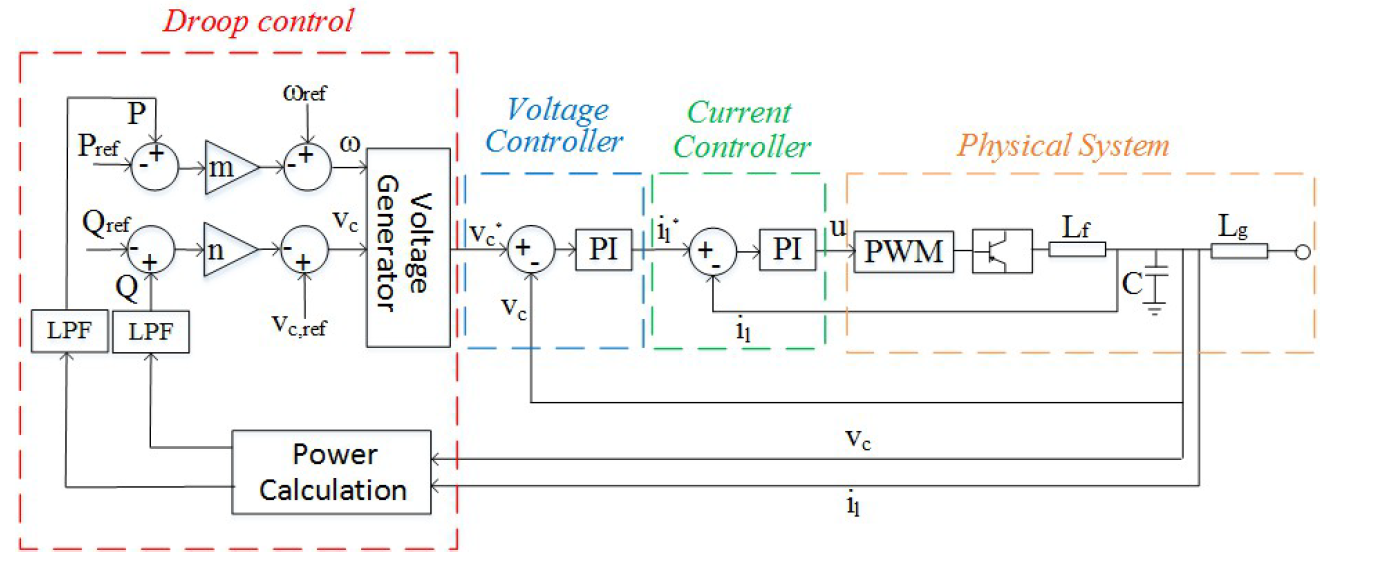

## Droop control

We assume the delta values

delta_f_max = 1;
delta_V_max = 10;
delta_omega_max = 2*pi*delta_f_max;

But we do not know yet the following values. ***(to be confirmed)***

***Also remember that we should consider our two sources supplying half of the power each!***

% Reference values
P_ref = 0;
Q_ref = 0;

% Inverter maximum powers
P_max = 0;
Q_max = 0;

% Inverter rated power
P = 0;
Q = 0;

% Calculation of power?? To be confirmed
R_total = 2*R_line + R_load;
L_total = 2*L_line + 2*L_f + 2*L_g;
X_total = 2*pi*f_n*L_total;
P_steady = V^2 / R_load;
Q_steady = V^2 / X_total;

Then calculate the droop coefficients

m_p = delta_omega_max / (2*P_max);
n_q = delta_V_max / (2*Q_max);

## Current Controller

Our PI for the **current control loop** design can be performed considering only the cosed loop function with gain: $G_{cl}(s) = \frac{1}{\tau_i s + 1}
$

f_s = 10e3; % Switching frequency
tau_i = 10 * f_s;

## Voltage Controller

The **voltage control loop** design is instead based on:


$$G_{cl}(s) = G_{PF}(s) *G_{cl}(s) = \frac{k_i}{s^2 + \left( \frac{k_p}{C_f} \right)s + \frac{k_i}{C_f}}
$$


The denominator has the standard form of a second order transfer function, so that $K_p$ and $K_i$ can be dimensioned as following:


$$k_p = 2\zeta \omega_n C_f 
$$
            
$$k_i = \omega_n^2 C_f 
$$
          
$$\tau_v = \frac{1}{\zeta \omega_n}$$


Where $\tau_v$ can also be calcoated as $\tau_v = 5 * \tau_i$ to ensure decoupling between control action, so we are able to calculate $\zeta$

tau_v = 5 * tau_i;
zeta = 1 / (omega_n * tau_v);
K_p = 2 * zeta * omega_n * C_f;
K_i = omega_n^2 * C_f;

## Phisical System

This system is represented by a LCL filter, where $L_f
$ and $C_f$ are part of the filter, and $L_g$ represents the grid side inductor.

We also assume to deal with ideal components, so that our Inductors and Capacitors do not have any stray parameter (e.g.: inner resistrance or parallel capacitance).

Also, we are required to define parameters for the PWM, but we can assume this to be pefectly ideal.

L_f = 3e-3;     % Converter side
C_f = 10e-6;    
L_g = 1.5e-3;   % Grid side